# Plot multiple oriented line segments

`ax = pvPlotCycle(vUnits,pUnits,V1,P1,...,Vn,Pn)` creates an oriented piecewise-defined line plot consisting of lines defined by `(V1(i),P1(i))` up through `(Vn(j),Pn(j))`. 

## Examples

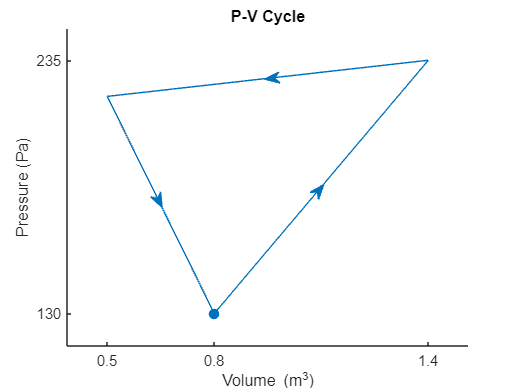

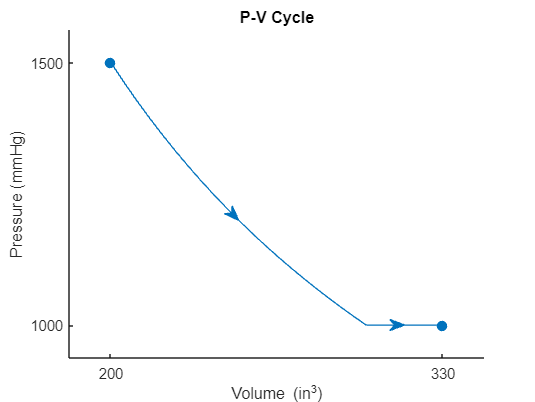

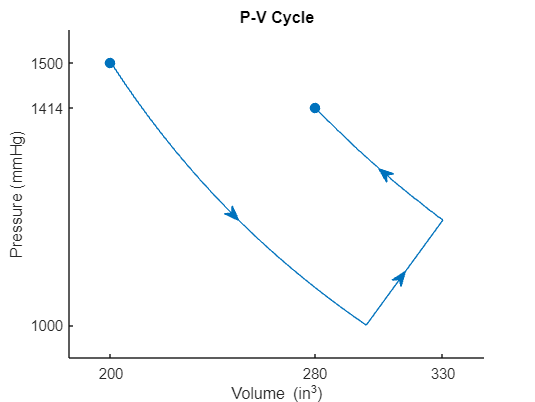

function ax = pvPlotCycle(vUnits,pUnits,vValues,pValues)
arguments
        vUnits (1,1) string
        pUnits (1,1) string
%         pvTitle string = "P-V plot"
end
arguments(Repeating)
    vValues (1,:) {mustBeReal,mustBeNumeric}
    pValues (1,:) {mustBeReal,mustBeNumeric}
end
    
clf
ax = axes;
allVVals = [vValues{:,:}];
allPVals = [pValues{:,:}];
xlabel("Volume (" + vUnits + ")")
ylabel("Pressure (" + pUnits + ")")
title("P-V Cycle")
setLabels(allVVals,"x",true)
setLabels(allPVals,"y",true)
xlim(getBounds(allVVals))
ylim(getBounds(allPVals))
ax.PositionConstraint = "innerposition";
pvLinePlot(ax,vValues,pValues);
if allVVals(1)==allVVals(end) && allPVals(1)==allPVals(end)
    fill(allVVals,allPVals,[0.9 0.9 0.9],"EdgeColor","none")
end
ax.Children = flipud(ax.Children);
end


function pvLinePlot(ax,vValues,pValues)
% Helper function to plot the lines, add the arrows, fix the colors, and
% identify the starting and ending points of the path
z = reshape([vValues;pValues],1,[]);
ax.NextPlot = "add";
p = plot(ax,z{:});

series1Color = p(1).Color;
for k = 2:numel(p)
p(k).Color = series1Color;
end

[axVals,ayVals] = cellfun(@(V,P) locateArrow(V,P,ax),vValues,pValues,'UniformOutput',false);
cellfun(@(x,y) annotation("arrow",x,y,"Color",series1Color),axVals,ayVals)

endPts = [vValues{1}(1) pValues{1}(1); vValues{end}(end) pValues{end}(end)];

ax.NextPlot = "add";
scatter(ax,endPts(:,1),endPts(:,2),50,"Filled","SeriesIndex",1)

end
